# **RS-HL-10: Time Variant MDP Functions**

**Oden Institute**

**Hongseok Kim**

**7/11/2024**

## Scope

- In this report, the function module and input/output analysis of Time Variant MDP of Satellite Simulation is Presented.

## I. Call the SAT-to-SAT Dataset

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('/workspace/RS_Dataset/RS_HL_3_dataset.mat')

## II. Run MDP

% Parameter Setting
time_index_vector = 1:20;
destination_state = 38;

% Run MDP
MDP = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_state);

## III. Simulation Test

start_time = 1;
start_state = 20;

% Run Simulation
[time_list, reward_list, state_list, state_value_list] = simulation_test(start_time,start_state,MDP,time_index_vector,destination_state);

simultion_result = [time_list, state_list, reward_list, state_value_list]

simultion_result =     1.0000   20.0000         0   53.0000
    2.0000   19.0000   -1.0000   61.5000
    3.0000   18.0000   -2.0000   70.0000
    4.0000   39.0000  -17.0000   92.5000
    5.0000   38.0000   83.0000         0


## IV.Analysis

### IV.1 State Value changing over time

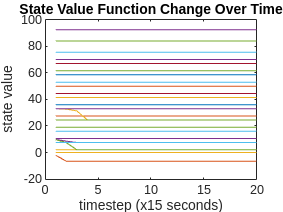

number_of_states = length(sat_to_sat_contact_3d_matrix(1,:,1));
state_value_over_time = zeros(length(time_index_vector),number_of_states);

for t = 1:length(time_index_vector)
    for state_index = 1:number_of_states
        state_value_over_time(t,state_index) = MDP.(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
    end
end

for state_index = 1:number_of_states
    plot(time_index_vector,state_value_over_time(:,state_index))
    hold on
end

hold off
title('State Value Function Change Over Time')
xlabel('timestep (x15 seconds)')
ylabel('state value')